# 演習11-1 オイラー法 

•微分方程式の初期値問題をオイラー法を使用して解く


$$\begin{array}{l}
y\left(0\right)=\mathrm{0}\\
\frac{\textrm{dy}}{\textrm{dx}}=y^2 -\textrm{ysin}\left(x\right)+\cos \left(x\right)
\end{array}$$


・積分区間


$$x=\left\lbrack 0,2\pi \right\rbrack$$


•ファイル後部にあるオイラー法のプログラム(euler)を完成させて使用する

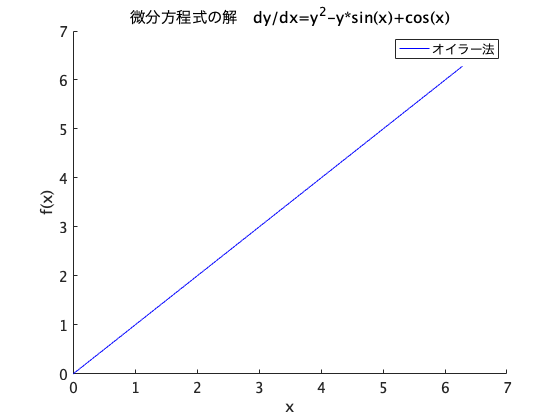

% オイラー法の呼び出し
y0=0; x=0:0.01:2*pi;
format longE;
yel=euler(y0,x,@f);

% グラフ作成
clf
hold on;
plot(x,yel,'b');% 微分方程式の解グラフ

graph = gca(); 
graph.FontSize =14;
graph.XAxisLocation = "origin";  % x軸の場所指定
xlabel('x');    % x軸ラベル
ylabel('f(x)');    % y軸ラベル
title('微分方程式の解　dy/dx=y^2-y*sin(x)+cos(x)'); 
legend('オイラー法');
hold off;

# 演習11-2 ルンゲクッタ法 

•微分方程式の初期値問題をオイラー法を使用して解く


$$\begin{array}{l}
y\left(0\right)=\mathrm{0}\\
\frac{\textrm{dy}}{\textrm{dx}}=y^2 -\textrm{ysin}\left(x\right)+\cos \left(x\right)
\end{array}$$


・積分区間


$$x=\left\lbrack 0,2\pi \right\rbrack$$


•ファイル後部にあるルンゲクッタ４次のプログラム(rk4)を完成させて使用する

% ルンゲクッタ法の呼び出し
y0=0, x=0:0.01:2*pi;

y0 =      0


format longE;
yrk=rk4(y0,x,@f);

出力引数 "ydash" (および他の引数もおそらく) は "ex11_q" の呼び出し中に代入されていません。

エラー: ex11_q (行 67)
    k1=f(x(j),y(j));


% グラフ作成
clf
hold on;
plot(x,yrk,'r');% 微分方程式の解グラフ

graph = gca(); 
graph.FontSize =14;
graph.XAxisLocation = "origin";  % x軸の場所指定
xlabel('x');    % x軸ラベル
ylabel('f(x)');    % y軸ラベル
title('微分方程式の解　dy/dx=y^2-y*sin(x)+cos(x)'); 
legend('ルンゲクッタ法');
hold off;

# ファイルの最後に関数定義を記述

微分導関数の定義

function ydash=f(x,y)
 % 1階微分導関数 ydashを定義する
 % 穴埋め
end

オイラー法，ルンゲクッタ法

function y=euler(y0,x,f)
%  オイラー法
%  初期値 y0 （スカラー）
%  解区間 x （ベクトル）
%  1階微分導関数 f　（関数名）
y=x; y(1)=y0;
n=size(x,2);
for j=1:n-1
    % 積分区間
    h=x(j+1)-x(j);
    %　導関数k=y'=f(x(j),y(j))
    % 穴埋め
    y=             
    %　オイラー法の公式
    % 穴埋め
end
end

function y=rk4(y0,x,f)
% ルンゲクッタ法
%  初期値 y0 （スカラー）
%  解区間 x （ベクトル）
%  1階微分導関数 f（関数名）
y=x; y(1)=y0;
n=size(x,2);
for j=1:n-1
    h=x(j+1)-x(j);
    k1=f(x(j),y(j));
    k2=f(x(j)+0.5*h,y(j)+0.5*h*k1);
    k3=f(x(j)+0.5*h,y(j)+0.5*h*k2);
    k4=f(x(j)+h,y(j)+h*k3);
    y(j+1)=y(j)+h/6*(k1+2*(k2+k3)+k4);
end
end
